%%function DSGN = generateDSGN(funcs, fmriprep_dir, task)    
    
    % 1. Set up directories and paths
    root = setRootDirectory();
    sidsubDict = setSubjectDictionary();

    root=fileparts(funcs(1).folder);
    fmriprep_dir='/dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/fmriprep/'
    
    % 2. Extract session, subject, and task information
    [sid, sub, sess, ~] = getSessionSubjectTask(funcs(1).name, sidsubDict);

    [sub, sess, ~] = getBIDSSubSesRunTask(funcs(1).name);

    sub = char(extractBetween(funcs(1).name, "sub-", "_ses"));
    sess = char(extractBetween(funcs(1).name, "ses-", "_"));
    run = char(extractBetween(funcs(1).name, "run-", "_"));
    % task = char(extractBetween(funcs(1).name, "task-", "_"));

    disp(['Currently processing sub-', sub, '_ses-',sess,'_run-',run, '_task-', task]);
    
    % 3. Set up metadata
    DSGN = setupMetadata(sub, sess, task, funcs);
    % 4. Set up directories



    DSGN = setupDirectories(root, fmriprep_dir, sub, run, task, DSGN);


    % 5. Set up design parameters
    DSGN = setupDesignParameters(DSGN);

    % 6. Process functional runs
    %     pyfolder = fullfile(root, 'labdata', 'data', 'WASABI', 'WASABI_public', 'fMRI Tasks', 'N-Of-Few');
    pyfolder = fullfile(root);

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 49.43%
Expected 35.00 outside 95% ellipsoid, found  32

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 1 2 
Uncorrected: 32 images		Cases 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 17 18 19 20 21 22 25 27 28 29 30 599 600 601 602 603 700 



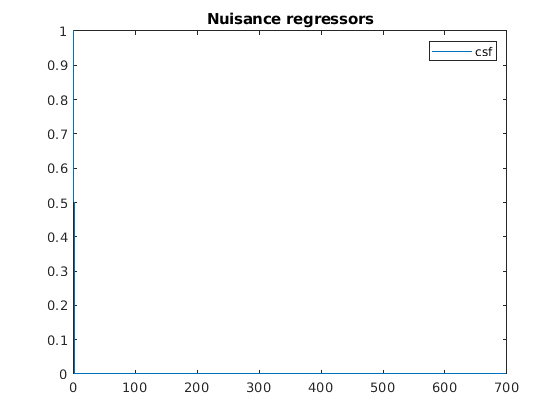

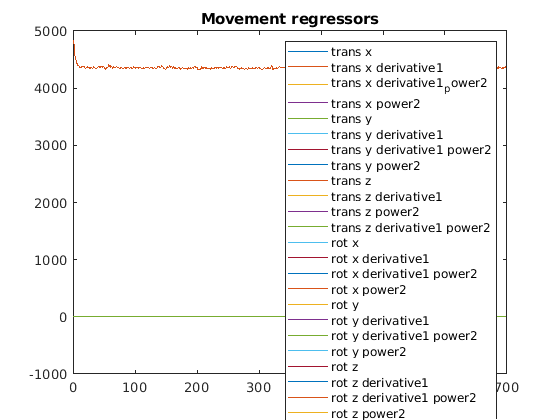

DSGN = struct with fields:
                 metadata: 'sub-SID000002 ses-01 task-pinellocalizer run-04 design structure'
                 modeldir: '/dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/canlab_firstlvl/sub-SID000002/ses-01/func/firstlvl/pinellocalizer'
                 subjects: {'/dartfs-hpc/rc/lab/C/CANlab/labdata/data/WASABI/derivatives/fmriprep/sub-SID000002'}
                funcnames: {'ses-01/func/run-01/sub-SID000002_ses-01_task-pinellocalizer_acq-mb8_run-04_space-MNI152NLin2009cAsym_desc-preproc_bold.nii'}
               conditions: {{0×1 cell}}
         modelingfilesdir: 'sub-SID000002_task-pinellocalizer_firstlvl'
         allowmissingfunc: 1
                       tr: 0.46
                      hpf: 180
                  fmri_t0: 8
                 multireg: 'noise_model.mat'
    allowmissingcondfiles: 1
                notimemod: 1
           allowemptycond: 1
                     fast: 1
                      ar1: 0


Error using generate_contrasts
No tasks defined, please define your tasks first to generate contrasts.

Error in generateDSGN>processFunctionalRuns (line 166)
        [DSGN.contrasts, DSGN.contrastweights, DSGN.contrastnames] = generate_contrasts(task);


    [DSGN, R] = processFunctionalRuns(funcs, task, sub, sess, DSGN);

% end


function root = setRootDirectory()
    if ismac()
        root = '/Volumes/CANlab';
    elseif ispc()
        root = '\\dartfs-hpc\rc\lab\C\CANlab';
    else
        root = '//dartfs-hpc/rc/lab/C/CANlab';
    end
end

% function sidsubDict = setSubjectDictionary()
%     sidKeys = {'SID001651', 'SID001852', 'SID001804', 'SID000002', 'SID001641', 'SID001684', 'SID001567', 'SID000743', 'SID002328', 'SID001907', 'SID002035'};
%     subValues = {'sub-00001', 'sub-00002', 'sub-00003', 'sub-00004', 'sub-00005', 'sub-00006', 'sub-00007', 'sub-00008', 'sub-00009', 'sub-01001', 'sub-01002'};
%     sidsubDict = containers.Map(sidKeys, subValues);
% end

% function [sid, sub, sess, task] = getSessionSubjectTask(funcName, sidsubDict)
%     sid = char(extractBetween(funcName, "sub-", "_ses"));
%     sub = sidsubDict(sid);
%     sess = char(extractBetween(funcName, "ses-", "_task"));
%     task = char(extractBetween(funcName, "task-", "_"));
% end


function [sub, sess, run, task] = getBIDSSubSesRunTask(funcName)
    sub = char(extractBetween(funcName, "sub-", "_ses"));
    sess = char(extractBetween(funcName, "ses-", "_task"));
    run = char(extractBetween(funcName, "ses-", "_task"));
    task = char(extractBetween(funcName, "task-", "_"));
end

function DSGN = setupMetadata(sub, sess, task, funcs)
    if length(funcs) == 1
        run = char(extractBetween(funcs(1).name, "run-", "_space"));
        DSGN.metadata = sprintf('sub-%s ses-%s task-%s run-%s design structure', sub, sess, task, run);
    elseif length(funcs) > 1
        runMin = char(extractBetween(funcs(1).name, "run-", "_space"));
        runMax = char(extractBetween(funcs(end).name, "run-", "_space"));
        DSGN.metadata = sprintf('sub-%s ses-%s task-%s runs-%s-%s design structure', sub, sess, task, runMin, runMax);
    end
end

function DSGN = setupDirectories(firstlvl_funcdir, fmriprep_dir, sub, run, task, DSGN)
    DSGN.modeldir = fullfile(firstlvl_funcdir, 'firstlvl', task);
    DSGN.subjects = {fullfile(fmriprep_dir, ['sub-', sub])};
    DSGN.funcnames = {};
    DSGN.conditions = {}; 
    DSGN.modelingfilesdir = sprintf('sub-%s_task-%s_firstlvl', sub, task);  % This folder gets appended to every session folder

    % Create folder to dump betas into
    if ~isfolder(DSGN.modeldir)
        mkdir(DSGN.modeldir)
    end

    % Create folder to dump regressor structs into
    if ~isfolder(DSGN.modelingfilesdir)
        mkdir(fullfile(firstlvl_funcdir, ['run-', run], DSGN.modelingfilesdir))
    end

end

function DSGN = setupDesignParameters(DSGN)
    % USER PLEASE ADJUST THESE:
    DSGN.allowmissingfunc = true;
    DSGN.tr = 0.46;
    DSGN.hpf = 180; % roughly 1/2 scan time
    DSGN.fmri_t0 = 8; % no idea what to set this to, we don't do slice timing correction
    DSGN.multireg = 'noise_model.mat'; % name of the things regressed out during preproc
    DSGN.allowmissingcondfiles = true;
    DSGN.notimemod = true; % provided by Bogdan
    DSGN.allowemptycond = true; % Not all condition combinations are present in every run.
    DSGN.fast = true;
    DSGN.ar1 = false;
end

function [DSGN, R] = processFunctionalRuns(funcs, task, sub, sess, DSGN)
    for i = 1:length(funcs)
        [sub, sess, run, ~] = getBIDSSubSesRunTask(funcs(i).name);

        % 1. Find the *_events.tsv file
        events_fname = fullfile(funcs(i).folder, '*_events.tsv');
        events_tsv = dir(events_fname);
        events_dat = importBIDSfile(fullfile(events_tsv.folder, events_tsv.name));

        DSGN.funcnames{end+1}=fullfile(['ses-' sess], 'func', ['run-', run], [erase(funcs(i).name, '.gz')]);  % Make sure you are only adding relative paths starting with session number the files you are adding are .nii and not .nii.gz
        model_path = fullfile(funcs(i).folder, [DSGN.modelingfilesdir filesep]);
        
        % 2. Find noise related files for the func
        noise_fname = fullfile(funcs(i).folder, '*confounds_timeseries.tsv');
        noise_tsv = dir(noise_fname);   % confounds_timseries.tsv regular expression search string.
        noise_dat = importBIDSfile(fullfile(noise_tsv.folder, noise_tsv.name));
        
        % 3. Generate RMSSD/DVARS Image-wise Nuisance Indicator vectors
        % Please note, fmriprep confounds include regressors for dvars,
        % framewise_displacement, rmsd, motion_outlier* and I am not sure
        % how well they compare with our rmssd methods so they are not used for now.
        if isfile([erase(funcs(i).name, '.nii'), '.mat'])
            load([erase(funcs(i).name, '.nii'), '.mat']);
        else
            image = fmri_data(fullfile(funcs(i).folder, funcs(i).name));
            save([erase(funcs(i).name, '.nii') '.mat'], 'image', '-mat');
        end
    
        R_spikes=[];
        [D2, D2_expected, pval, wh_outlier_uncorr, wh_outlier_corr] = mahal(image, 'noplot');
        outlier_index=find(wh_outlier_uncorr==1);     % You can toggle between the two: corrected or uncorrected outliers.
        % outlier_index=find(wh_outlier_corr==1);
        if length(outlier_index)>0
           for covi=1:length(outlier_index)
              A=zeros(1,size(image.dat,2));
              A(outlier_index(covi))=1;   %%%%% Outlier regressor e.g [0 0 0 0 0 0 1 0 0 0 0 0 ....]
              R_spikes=[R_spikes A'];
           end
        end
    
        if isfile(['sub-' sub '_ses-' sess '_task-' task '_run-' run '_rmssd-movie.tiff'])
            [rmssd, rmssd_outlier_regressor_matrix] = rmssd_movie(image, 'nomovie');
        else
            [rmssd, rmssd_outlier_regressor_matrix] = rmssd_movie(image, 'writetofile', 'movieoutfile', ['sub-' sub '_ses-' sess '_task-' task '_run-' run '_rmssd-movie.tiff']);
        end
        R_dvars = rmssd_outlier_regressor_matrix;  % save these
        R = [R_spikes R_dvars];
    
        % 4. Generate regressors. Call a generate_WASABI_regressors function to do most of the heavy lifting.
        DSGN.conditions{end+1}=generate_regressors(task, sub, sess, events_dat, noise_dat, R, model_path)

        % 5. Generate contrasts. Call generate_WASABI_contrasts function to do most of the heavy lifting.
        [DSGN.contrasts, DSGN.contrastweights, DSGN.contrastnames] = generate_contrasts(task);
    end
end





%     % Code for processing functional runs goes here...
% 
%     for i = 1:length(funcs)
%         run = str2num(char(extractBetween(funcs(i).name, 'run-', '_space')));
%         
%         % 2. Find task related files for the func
%         % Should be able to find it
%         try
%             sessionFolderPath = fullfile(pyfolder, ['WASABI ' task], 'data', sub, ['ses-' sess]);
%             if contains(task, 'pinellocalizer')
%                 cd(sessionFolderPath);
%                 file = dir('*.tsv');
%                 stim_dat_fname = file.name;
%             elseif contains(task, 'bodymap')
%                 stim_dat_fname = fullfile(sessionFolderPath, sprintf('%s_*_task-%s_*_run-*%d_events.tsv', sub, task, run));
%             elseif contains(task, 'acceptmap')
%                 stim_dat_fname = fullfile(sessionFolderPath, sprintf('%s_*_run-*%d_events.tsv', sub, run));
%             else
%                 cd(sessionFolderPath);
%             end
%         catch
%             error('Could not find the appropriate python folder to fetch behavioral data for image file %s', funcs(i).name);
%         end
% 
%     
%         % ... (rest of your code remains unchanged until the try-catch block for importing stimulation data)
%        
% 
%         try
%             if contains(task, 'hyperalignment')
%                 stim_dat_fname = sprintf('%s_*_events.tsv', sub);
%             elseif contains(task, 'distractmap')
%                 stim_dat_fname = sprintf('%s_*task-distractmap_*_run-*%d_events.tsv', sub, run);
%                 stim_dat = dir(stim_dat_fname);
%                 if length(stim_dat) > 1
%                     stim_dat_fname = sprintf('%s_*task-distractmap_*_run-*%d_events.tsv', sub, run);
%                 end
%             elseif ~exist('stim_dat_fname', 'var')
%                 stim_dat_fname = sprintf('%s_*_run-*%d_events.tsv', sub, run);
%             end
%             
%             stim_dat = dir(stim_dat_fname);
%             stim_dat_fname = stim_dat.name;
%             stim_dat_folder = stim_dat.folder;
% 
%             
%             opts = detectImportOptions(stim_dat.name, 'FileType', 'delimitedtext', 'Delimiter', '\t');
%             if sum(ismember(opts.VariableNames, 'trial_type')) > 0
%                 opts = setvartype(opts, 'trial_type', 'char');
%             end
%             stim_dat = readtable(stim_dat.name, opts);
%         catch
%             error('Could not import stimulation data matching the filename %s for image file %s', stim_dat_fname, funcs(i).name);
%         end
% 
% 
%         % ... (rest of your code remains unchanged)
%     end
% 
%     run = char(extractBetween(funcs(i).name, "run-","_space")); % Since run for stim_data and run for fmri_data may not match...
%     runfolder=fullfile(funcs(i).folder, ['run-', run]);
%     %
%     DSGN.funcnames{end+1}=['ses-' sess, filesep, 'func', filesep, 'run-', run, filesep, erase(funcs(i).name, '.gz')];  % Make sure you are only adding relative paths starting with session number the files you are adding are .nii and not .nii.gz
%     %
%     model_path = [funcs(i).folder, filesep, ['run-', run] filesep DSGN.modelingfilesdir filesep];
% 
%     cd(funcs(i).folder)
%     % noise vectors need to be generated uniquely for each run.
% 
% 
%     % 3. Find noise related files for the func
%     noise_fname = ['*ses-', sess, '_*run-', run, '_*confounds_timeseries.tsv'];
%     noise_tsv = dir(['*ses-', sess, '_task-', task, '_*run-', run, '_*confounds_timeseries.tsv']);   % confounds_timseries.tsv regular expression search string.
%     
%     if (isdir(runfolder))
%         cd(runfolder) % Return to the func/run-XX folder to save condition and noise structures
%     else
%         mkdir(runfolder)
%         if ispc()
%             system(['mklink ', runfolder, filesep, funcs(i).name, ' ', fullfile(funcs(i).folder,funcs(i).name)])
%             system(['mklink ', runfolder, filesep, noise_tsv.name, ' ', fullfile(noise_tsv.folder, noise_tsv.name)])
%             system(['mklink ', runfolder, filesep, stim_dat.name, ' ', fullfile(stim_dat.folder, stim_dat.name)])
%         else
%             system(['ln -sv ', fullfile(funcs(i).folder,funcs(i).name), ' ', runfolder])  % Create a symlink to nifti file
%             system(['ln -sv ', fullfile(noise_tsv.folder, noise_tsv.name), ' ', runfolder])  % Create a symlink to noise file
%             system(['ln -sv ', fullfile(stim_dat_folder, stim_dat_fname), ' ', runfolder]) % Create a symlink to python file
%         end
%         cd(runfolder)
%     end
%     
%     try
% %             fid = fopen([noise_tsv.folder,filesep,noise_tsv.name]);
% %             noise_hdr = strsplit(fgetl(fid));
% %             noise_dat = textscan(fid,[repmat('%f',1,length(noise_hdr))],...
% %                 'Delimiter',{'\t',' '},...
% %                 'MultipleDelimsAsOne',1,'ReturnOnError',false,...
% %                 'CollectOutput',1,'TreatAsEmpty','n/a','EndOfLine','\n');
% %             fclose(fid);
%         noise_dat = readtable(noise_tsv.name, 'FileType', 'delimitedtext');     % Read the events file
%     catch
%         warning(sprintf('Could not import confounds for %s, skipping...\n', noise_fname));
%     end
% 
% 
% 
%     % 4. Generate Spike Regressors
% 
%     %%%%%%%%% Generate 'spike' outlier regressor  %%%%%%%
%     % cd(strcat(DSGN.subjects{j},filesep,DSGN.funcnames{j}(1:17))) % 'ses-XX\func\run-X' move into the run folder
%     spm('Defaults','fMRI')
%     if isfile([erase(funcs(i).name, '.nii'), '.mat'])
%         load([erase(funcs(i).name, '.nii'), '.mat']);
%     else
%         image = fmri_data(funcs(i).name);
%         save([erase(funcs(i).name, '.nii') '.mat'], 'image', '-mat');
%     end
% 
%     % Tor's way
% %         [wh_outlier_uncorr, wh_outlier_corr] = plot(image);
% %         R_spikes = intercept_model(size(dat.dat, 2), find(wh_outlier_uncorr));
% %         R_spikes = R_spikes(:, 2:end);  % remove initial intercept column
% 
%     % Ke's way
%     R_spikes=[];
%     [D2, D2_expected, pval, wh_outlier_uncorr, wh_outlier_corr] = mahal(image, 'noplot');
%     outlier_index=find(wh_outlier_uncorr==1);     % You can toggle between the two: corrected or uncorrected.
%     % outlier_index=find(wh_outlier_corr==1);
%     if length(outlier_index)>0
%        for covi=1:length(outlier_index)
%           A=zeros(1,size(image.dat,2));
%           A(outlier_index(covi))=1;   %%%%% Outlier regressor e.g [0 0 0 0 0 0 1 0 0 0 0 0 ....]
%           R_spikes=[R_spikes A'];
%        end
%     end
% 
%     if isfile(['sub-' sub '_ses-' sess '_task-' task '_run-' run '_rmssd-movie.tiff'])
%         [rmssd, rmssd_outlier_regressor_matrix] = rmssd_movie(image, 'nomovie');
%     else
%         [rmssd, rmssd_outlier_regressor_matrix] = rmssd_movie(image, 'writetofile', 'movieoutfile', ['sub-' sub '_ses-' sess '_task-' task '_run-' run '_rmssd-movie.tiff']);
%     end
%     R_dvars = rmssd_outlier_regressor_matrix;  % save these
%     R = [R_spikes R_dvars];
%     % R = [R_spikes R_dvars rp2];
% 
%     % 3. Generate regressors. Call a generate_WASAB_regressors function to do most of the heavy lifting.
%     
%     % Create folder to dump regressor structs into
%     if ~isfolder(DSGN.modelingfilesdir)
%         mkdir(DSGN.modelingfilesdir)
%     end
%     
%     switch true
%         case contains(task, {'bodymap', 'distractmap', 'acceptmap'})
%             % Extract bodysite name to revise the condition names:
%             Sitename=extractBetween(stim_dat_fname,"acq-","_run");
%             DSGN.conditions{end+1}=generate_WASABI_regressors(task, sub, sess, stim_dat, noise_dat, R, model_path, Sitename)
%         otherwise 
%             DSGN.conditions{end+1}=generate_WASABI_regressors(task, sub, sess, stim_dat, noise_dat, R, model_path)
%     end
%     
% 
%     [DSGN.contrasts, DSGN.contrastweights, DSGN.contrastnames] = generate_WASABI_contrasts(task);
% 
% 
% 
% 
% end



function DSGN = generateDSGN(funcs)    
    
    if ismac()
        root = '/Volumes/CANlab'
    elseif ispc()
        root = '\\dartfs-hpc\rc\lab\C\CANlab'
    else
        root = '//dartfs-hpc/rc/lab/C/CANlab'
    end

    sidKeys = {'SID001651','SID001852','SID001804','SID000002','SID001641','SID001684','SID001567','SID000743','SID002328','SID001907','SID002035'};
    subValues = {'sub-00001','sub-00002','sub-00003','sub-00004','sub-00005','sub-00006','sub-00007','sub-00008', 'sub-00009', 'sub-01001','sub-01002'};
    sidsubDict = containers.Map(sidKeys, subValues);

    sid = char(extractBetween(funcs(1).name, "sub-","_ses"));
    sub = sidsubDict(sid);
    sess = char(extractBetween(funcs(1).name, "ses-","_task"));
    task = char(extractBetween(funcs(1).name, "task-","_"));    % Could be between _acq or _run...
    
    disp(['Currently processing ', task]);

    if length(funcs) == 1
        run = char(extractBetween(funcs(1).name, "run-","_space"));
        DSGN.metadata = ['WASABI sub-' sid ' ses-' sess ' task-' task ' run-' run ' design structure'];
    elseif length(funcs) > 1
        runMin = char(extractBetween(funcs(1).name, "run-","_space"));
        runMax = char(extractBetween(funcs(end).name, "run-","_space"));
        DSGN.metadata = ['WASABI sub-' sid ' ses-' sess ' task-' task ' runs-' runMin '-' runMax ' design structure'];
    end

    % Change these all to linux directories in Discovery
    if contains(task, 'acceptmap')
        DSGN.modeldir = fullfile([root, '/labdata/data/WASABI/derivatives/fmriprep/sub-',  sid], ['ses-', sess], 'func', 'firstlvl', 'acceptmap');
    else
        DSGN.modeldir = fullfile([root, '/labdata/data/WASABI/derivatives/fmriprep/sub-',  sid], ['ses-', sess], 'func', 'firstlvl', task);
   
    end
    DSGN.subjects={fullfile(root, ['/labdata/data/WASABI/derivatives/fmriprep/sub-', sid])};
    DSGN.funcnames={};
    DSGN.conditions={}; 

    DSGN.allowmissingfunc = true;
    DSGN.tr = 0.46;
    DSGN.hpf = 180; %roughly 1/2 scan time
    DSGN.fmri_t0 = 8; % no idea what to set this to, we don't do slice timing correction
    % This should be a natural integer number above 0. SPM Default is 8.
    % DSGN.singletrials = {{0,0}};

    DSGN.modelingfilesdir = ['sub-',  sid, '_task-', task, '_firstlvl'];  % This folder gets appended to every session folder
    DSGN.multireg = 'noise_model.mat'; % name of the things regressed out during preproc
    DSGN.allowmissingcondfiles = true;
    DSGN.notimemod = true; % provided by Bogdan
    DSGN.allowemptycond = true; % Not all condition combinations are present in every run.

% | - DSGN.fast (DEFAULT: false)                                                   |
% |     if true, uses the FAST autoregressive model to model serial correlations.  |
% |       This method was developed for sub-second TRs. For detals see Bollmann,   |
% |       et al. (2018) Neuroimage.                                                |
% |     Note: if DSGN.fast = true, DSGN.ar1 must be false. These are mutually      |
% |       exclusive options.                                                       |
% |     Note: the resultant SPM.mat files may be quite large. You may need to      |
% |       spm_defaults.m to set defaults.mat.format to '-v7.3' to save them.       |
% |     Note: does not yet support multisession concatenated designs. Covariance   |
% |       structure will not be constrained to subcomponent scans.   
    DSGN.fast = true;
    DSGN.ar1 = false;

    pyfolder=fullfile(root,'labdata','data','WASABI', 'WASABI_public', 'fMRI Tasks', 'N-Of-Few');

    % 1. for each func in funcs
    for i=1:length(funcs)  
        % parse filename for important parameters:
%         run = num2str(i); 
        run=char(extractBetween(funcs(i).name,'run-','_space'));
        run = str2num(run);

        % 2. Find task related files for the func:      

        try % import stim data saved by matlab during scan
            if contains(task, 'pinellocalizer')
                cd([fullfile(pyfolder, ['WASABI ' task], 'data', sub, ['ses-' sess])]); % Move into the appropriate session folder
                file = dir('*.tsv');
                % stim_dat_fname = [sub, '_task-pinel_ses-',sess,'.tsv'];      % the regular expression search string
                stim_dat_fname = file.name;
            elseif contains(task, 'bodymap')
                cd([fullfile(pyfolder, 'WASABI bodymap', 'data', sub, ['ses-' sess])]); % Move into the appropriate session folder
                stim_dat_fname = [sub, '*_task-', task, '*_run-*',num2str(run),'_events.tsv'];      % the regular expression search string
            elseif contains(task, 'acceptmap')
                cd([fullfile(pyfolder, 'WASABI acceptmap', 'data', sub, ['ses-' sess])]); % Move into the appropriate session folder
                stim_dat_fname = [sub, '*_run-*',num2str(run),'_events.tsv'];
            else
                cd([fullfile(pyfolder, ['WASABI ' task], 'data', sub, ['ses-' sess])]); % Move into the appropriate session folder
            end
        catch
         
            error(['Could not find the appropriate python folder to fetch behavioral data for image file ' funcs(i).name]);
        end

        try
            if contains(task, 'hyperalignment')
                stim_dat_fname = [sub,'*_events.tsv'];
            elseif contains(task, 'distractmap')
                stim_dat_fname = [sub, '*task-distractmap', '*_run-*',num2str(run),'_events.tsv']
                stim_dat=dir(stim_dat_fname);
                if length(stim_dat)>1   % This is an issue when we had task-distractmap as well as task-distractmap-ratings
                    stim_dat_fname = [sub, '*task-distractmap_', '*_run-*',num2str(run),'_events.tsv']
                end
            elseif ~exist('stim_dat_fname', 'var')
                stim_dat_fname = [sub, '*_run-*',num2str(run),'_events.tsv']
            end
            stim_dat=dir(stim_dat_fname);                         % Find the events file
            stim_dat_fname = stim_dat.name;
            stim_dat_folder = stim_dat.folder;
            opts = detectImportOptions(stim_dat.name, 'FileType', 'delimitedtext', 'Delimiter', '\t');
            if sum(ismember(opts.VariableNames, 'trial_type')) > 0  % Check if 'trial_type" variable column exists.
                opts = setvartype(opts, 'trial_type', 'char');
            end
            % stim_dat = readtable(stim_dat.name, 'FileType', 'delimitedtext', 'Delimiter', '\t');     % Read the events file
            stim_dat = readtable(stim_dat.name, opts)
            % stim_dat = readcell(stim_dat.name, 'FileType', 'delimitedtext', 'Delimiter', '\t');     % Read the events file
            % stim_dat = table2cell(stim_dat); % convert table to cell array because tables are slow
            % stim_dat{1,1}='row';
            % stim_dat = cell2table(stim_dat(2:end,:), 'VariableNames',stim_dat(1,:))
            % stim_dat = tsvread(stim_dat.name)
        catch
 
            error(['Could not import stimulation data matching the filename ' stim_dat_fname ' for image file ' funcs(i).name]);
        end

        run = char(extractBetween(funcs(i).name, "run-","_space")); % Since run for stim_data and run for fmri_data may not match...
        runfolder=fullfile(funcs(i).folder, ['run-', run]);
        DSGN.funcnames{end+1}=['ses-' sess, filesep, 'func', filesep, 'run-', run, filesep, erase(funcs(i).name, '.gz')];  % Make sure you are only adding relative paths starting with session number the files you are adding are .nii and not .nii.gz
        model_path = [funcs(i).folder, filesep, ['run-', run] filesep DSGN.modelingfilesdir filesep];

        cd(funcs(i).folder)
        % noise vectors need to be generated uniquely for each run.
        % 3. Find noise related files for the func
        noise_fname = ['*ses-', sess, '_*run-', run, '_*confounds_timeseries.tsv'];
        noise_tsv = dir(['*ses-', sess, '_task-', task, '_*run-', run, '_*confounds_timeseries.tsv']);   % confounds_timseries.tsv regular expression search string.
        
        if (isdir(runfolder))
            cd(runfolder) % Return to the func/run-XX folder to save condition and noise structures
        else
            mkdir(runfolder)
            if ispc()
                system(['mklink ', runfolder, filesep, funcs(i).name, ' ', fullfile(funcs(i).folder,funcs(i).name)])
                system(['mklink ', runfolder, filesep, noise_tsv.name, ' ', fullfile(noise_tsv.folder, noise_tsv.name)])
                system(['mklink ', runfolder, filesep, stim_dat.name, ' ', fullfile(stim_dat.folder, stim_dat.name)])
            else
                system(['ln -sv ', fullfile(funcs(i).folder,funcs(i).name), ' ', runfolder])  % Create a symlink to nifti file
                system(['ln -sv ', fullfile(noise_tsv.folder, noise_tsv.name), ' ', runfolder])  % Create a symlink to noise file
                system(['ln -sv ', fullfile(stim_dat_folder, stim_dat_fname), ' ', runfolder]) % Create a symlink to python file
            end
            cd(runfolder)
        end
        
        try
%             fid = fopen([noise_tsv.folder,filesep,noise_tsv.name]);
%             noise_hdr = strsplit(fgetl(fid));
%             noise_dat = textscan(fid,[repmat('%f',1,length(noise_hdr))],...
%                 'Delimiter',{'\t',' '},...
%                 'MultipleDelimsAsOne',1,'ReturnOnError',false,...
%                 'CollectOutput',1,'TreatAsEmpty','n/a','EndOfLine','\n');
%             fclose(fid);
            noise_dat = readtable(noise_tsv.name, 'FileType', 'delimitedtext');     % Read the events file
        catch
            warning(sprintf('Could not import confounds for %s, skipping...\n', noise_fname));
        end



        % 4. Generate Spike Regressors

        %%%%%%%%% Generate 'spike' outlier regressor  %%%%%%%
        % cd(strcat(DSGN.subjects{j},filesep,DSGN.funcnames{j}(1:17))) % 'ses-XX\func\run-X' move into the run folder
        spm('Defaults','fMRI')
        if isfile([erase(funcs(i).name, '.nii'), '.mat'])
            load([erase(funcs(i).name, '.nii'), '.mat']);
        else
            image = fmri_data(funcs(i).name);
            save([erase(funcs(i).name, '.nii') '.mat'], 'image', '-mat');
        end
    
        % Tor's way
%         [wh_outlier_uncorr, wh_outlier_corr] = plot(image);
%         R_spikes = intercept_model(size(dat.dat, 2), find(wh_outlier_uncorr));
%         R_spikes = R_spikes(:, 2:end);  % remove initial intercept column
    
        % Ke's way
        R_spikes=[];
        [D2, D2_expected, pval, wh_outlier_uncorr, wh_outlier_corr] = mahal(image, 'noplot');
        outlier_index=find(wh_outlier_uncorr==1);     % You can toggle between the two: corrected or uncorrected.
        % outlier_index=find(wh_outlier_corr==1);
        if length(outlier_index)>0
           for covi=1:length(outlier_index)
              A=zeros(1,size(image.dat,2));
              A(outlier_index(covi))=1;   %%%%% Outlier regressor e.g [0 0 0 0 0 0 1 0 0 0 0 0 ....]
              R_spikes=[R_spikes A'];
           end
        end
    
        if isfile(['sub-' sid '_ses-' sess '_task-' task '_run-' run '_rmssd-movie.tiff'])
            [rmssd, rmssd_outlier_regressor_matrix] = rmssd_movie(image, 'nomovie');
        else
            [rmssd, rmssd_outlier_regressor_matrix] = rmssd_movie(image, 'writetofile', 'movieoutfile', ['sub-' sid '_ses-' sess '_task-' task '_run-' run '_rmssd-movie.tiff']);
        end
        R_dvars = rmssd_outlier_regressor_matrix;  % save these
        R = [R_spikes R_dvars];
        % R = [R_spikes R_dvars rp2];

        % 3. Generate regressors. Call a generate_WASAB_regressors function to do most of the heavy lifting.
        
        % Create folder to dump regressor structs into
        if ~isfolder(DSGN.modelingfilesdir)
            mkdir(DSGN.modelingfilesdir)
        end
        
        switch true
            case contains(task, {'bodymap', 'distractmap', 'acceptmap'})
                % Extract bodysite name to revise the condition names:
                Sitename=extractBetween(stim_dat_fname,"acq-","_run");
                DSGN.conditions{end+1}=generate_WASABI_regressors(task, sid, sess, stim_dat, noise_dat, R, model_path, Sitename)
            otherwise 
                DSGN.conditions{end+1}=generate_WASABI_regressors(task, sid, sess, stim_dat, noise_dat, R, model_path)
        end
        

        [DSGN.contrasts, DSGN.contrastweights, DSGN.contrastnames] = generate_WASABI_contrasts(task);
    end

%     This is for if our conditions get fucked up. This will add to
%     DSGN.conditions, any .mat file it sees in the firstlvl folder.
%     DSGN.conditions = {}
%     for j=1:length(DSGN.funcnames)
%         runfolder = extractBetween(DSGN.funcnames{j},'func/','/sub-')
%         cd(string(fullfile(DSGN.subjects{1}, ['ses-',sess], 'func', runfolder,['sub-SID001651_task-', task, '_firstlvl'])))
%         conditions=dir('*.mat')
%         conditions=strrep({conditions.name},'.mat','')
%         conditions=conditions(~ismember(conditions,'noise_model')) % remove noise_model from list of conditions
%         DSGN.conditions{end+1}=conditions
%     end

end